# Single-Track Vehicle Model

*by Ing. Denis Efremov*

## Introduction

Compared to the previously discussed kinematic model of a vehicle, the single-track (a.k.a. *bicycle model*) uses car's dynamics as its core function. This model is more precise comparing the real car physics. However, it is still based according some assumptions, namelly:

- all lifting, rolling, and pitching motion are neglected,

- vehicle mass is assumed to be concentrated at the center of gravity,

- front and rear tires are represented as one single tire on each axle; imaginary contact points of tires and surface are assumed to lie along the center of axles,

- pneumatic trail and aligning torque resulting from a sideslip angle of a tire are neglected,

- mass distribution on the axles is assumed to be constant.

There is a way to augment a basic single-track model for each assumption. Those augmentations could lead to a more precise vehicle model (and more complex). Commonly those tries end with a twin-track model [1] (or even multibody model [2]), which will not be considered during this course. The basic single-track model can be analyzed on the 0-2 Hz frequency spectrum [2], which suits to control, for example, lateral vehicle dynamics.

## General Idea

The core idea of the single-track is lumping together both wheels on each axle and describing forces that act on each tire/wheel. The vehicle is assumed to be one mass point, placed at the center of gravity (CG). Tires and wheels act on the rigid body dynamics by traction forces $F_{\rm x,f}$, $F_{\rm y,f}$, $F_{\rm x,r}$, $F_{\rm y,r}$. Whole vehicle dynamics is then described using states:

- $v$ (m/s, magnitude of the velocity vector),

- $\beta$ (rad, sideslip angle),

- $r$ (rad/s, yaw rate, or how fast the vehicle rotates around its CG),

- $\omega_{\rm f}$ (rad/s, angular velocity of the front axle),

- $\omega_{\rm r}$ (rad/s, angular velocity of the rear axle),

- $x_{\rm pos}$ (m, x coordinate of the position of CG),

- $y_{\rm pos}$ (m, y coordinate of the position of CG),

- $\psi$ (rad, heading of the vehicle).

The last three states are the same as in the kinematic vehicle model. It serves to work with vehicle position and could be omitted when we are not interested in it.

Inputs, which are assumed:

- $\delta_{\rm f}$ (rad, steering angle of the front axle),

- $\delta_{\rm r}$ (rad, steering angle of the rear axle),

- $\tau_{\rm df}$ (Nm, driving torque applied on the front axle),

- $\tau_{\rm bf}$ (Nm, braking torque applied on the front axle),

- $\tau_{\rm dr}$ (Nm, driving torque applied on the rear axle),

- $\tau_{\rm br}$ (Nm, braking torque applied on the rear axle).

Most braking and traction control systems algorithms work with drive and braking torques. However, in some systems, when we are not interested in wheel dynamics, one can use wheels' angular velocities as inputs of the model instead of torques, reducing by this step two dynamical equations from the core dynamics.

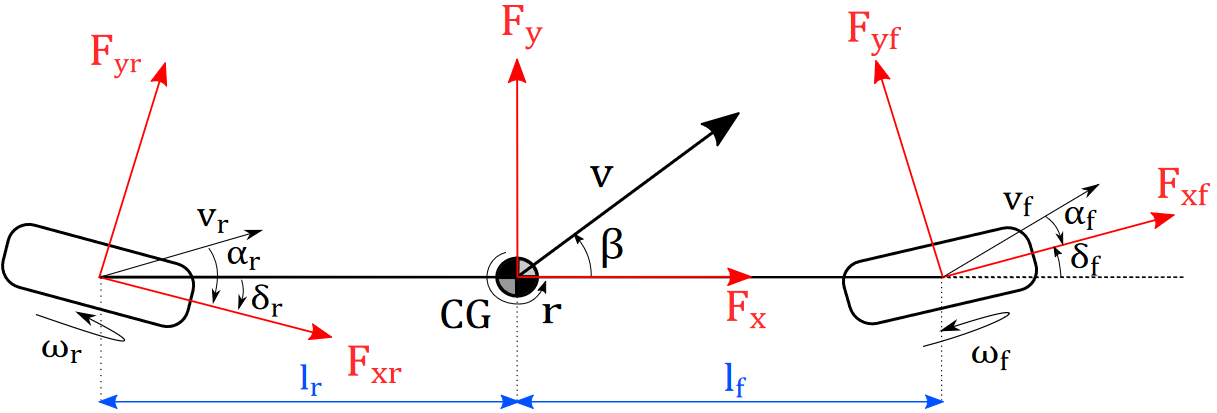Fig.1: Schematic model of a car. Source: [3]

The whole vehicle model can be separated into the following block for simplicity (see block diagram below). Each block has its purpose:

- **rigid body dynamics**, which represents a chassis;

- **steering angles projection** block computes longitudinal and lateral forces and angular momentum acting on the rigid body**;**

- **tire models** block calculates tire forces from slip variables;

- **wheel kinematics**, which calculates sideslip angles of the tires in the particular coordinate frame;

- **slip ratios **calculation part, which computes how each wheel spins;

- **wheel dynamics **part stands for the wheel rotational dynamics.

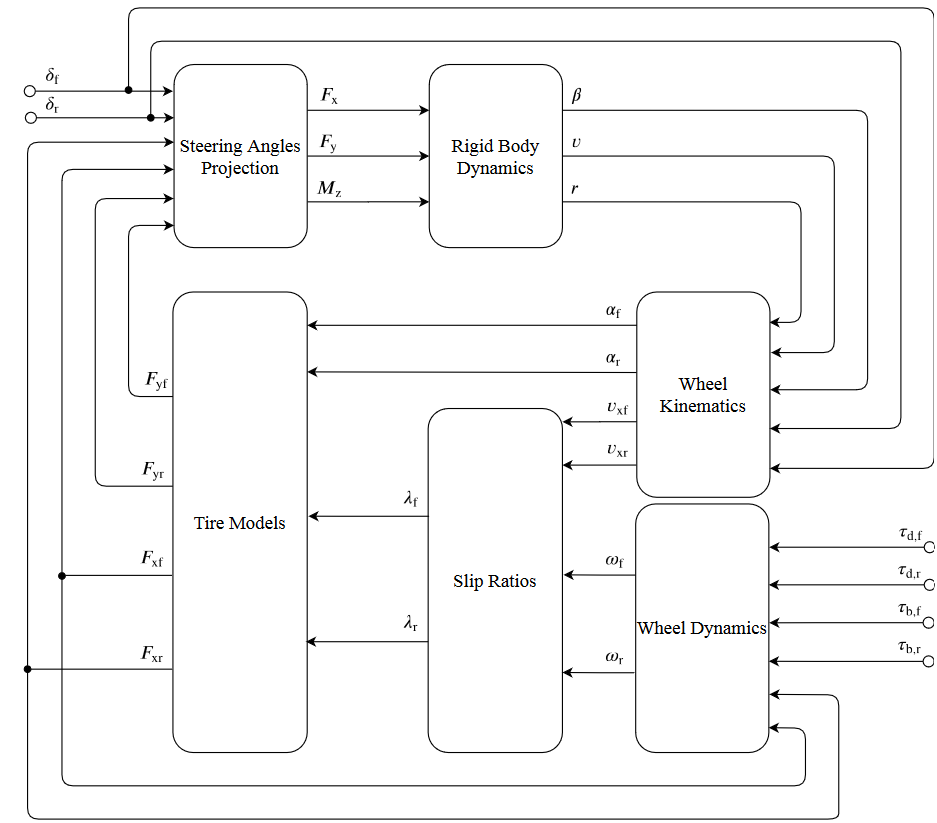Fig.2: Block-diagram of the single-track model. Source: [3]

## Tasks list

Your task is to implement each block as a code function and combine the whole vehicle model.

1) Implement riding body dynamics. What numerical problem can arise here?

 "Division by 0"

 Try to solve it using the if-else statement.

2) Implement steering angle projection calculation.

3) Implement tire model block. Assume a two-lines model for both forces for each axle:

 
$$F = \begin{cases} c \cdot \alpha, when |\alpha| < \frac{F_{max}}{c},\\ F_{max}, when |\alpha| \geq \frac{F_{max}}{c}.\end{cases} $$
 

4) Implement wheel kinematics calculation.

5) Implement wheel dynamics.

6) Implement a block for slip ratio calculation.

7) Combine everything in one function. Do not forget to augment your model with position coordinates of the CG and vehicle's heading angle, as done in the kinematic model.

8) Answer the following questions: 

-  Will this car model stops without applying braking torque on any axle?

-  What is a general source of braking (except inputs) in vehicle dynamics?

-  How could they be introduced in this model?

-  Does the model work well around zero velocity?

## Simulation ride tests

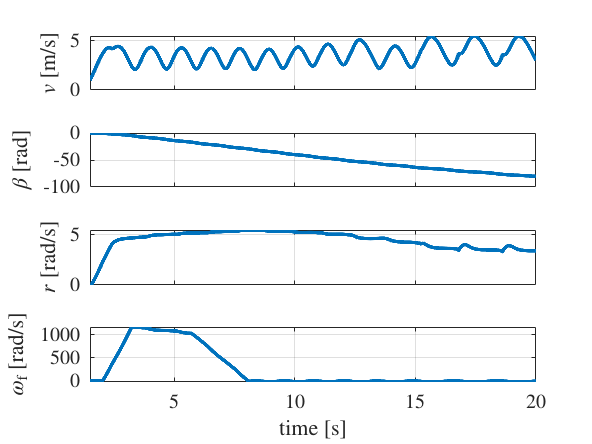

load('single_track_data.mat')
% initialize car parameters
initCar; 

% crop data from CarMaker
start_time = 1500;
t_taken = start_time:20000;

% states of the model will be stored here
vode = zeros(length(inputs.Data(t_taken,1)),1);
betaode = zeros(length(inputs.Data(t_taken,1)),1);
rode = zeros(length(inputs.Data(t_taken,1)),1);
wfode = zeros(length(inputs.Data(t_taken,1)),1);
wrode = zeros(length(inputs.Data(t_taken,1)),1);
xode = zeros(length(inputs.Data(t_taken,1)),1);
yode = zeros(length(inputs.Data(t_taken,1)),1);
psiode = zeros(length(inputs.Data(t_taken,1)),1);

% simulation time
time = inputs.Time(t_taken,1);

% ODE settings
options_ode = odeset('Maxstep', 10e-4, 'MaxOrder', 5, 'AbsTol', 1e-7); %4 7

% simulation
x_prev = [1, 0, 0, 1/car.rad, 1/car.rad, 0, 0, 0]; % init state
vode(1) = x_prev(1);
betaode(1) = x_prev(2);
rode(1) = x_prev(3);
wfode(1) = x_prev(4);
wrode(1) = x_prev(5);
xode(1) = x_prev(6);
yode(1) = x_prev(7);
psiode(1) = x_prev(8);
for k = 1:length(time)-1
    u = inputs.Data(start_time+k,:);
    [~, x] = ode15s(@single_track, [time(k) time(k+1)], x_prev, options_ode, u, car);
    vode(k+1) = x(end,1);
    betaode(k+1) = x(end,2);
    rode(k+1) = x(end,3);
    wfode(k+1) = x(end,4);
    wrode(k+1) = x(end,5);
    xode(k+1) = x(end,6);
    yode(k+1) = x(end,7);
    psiode(k+1) = x(end,8);
    x_prev = x(end,:);
end

% plotting
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
subplot(4,1,1)
plot(time, vode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$v$ [m/s]', 'Interpreter','latex')
subplot(4,1,2)
plot(time, betaode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$\beta$ [rad]', 'Interpreter','latex')
subplot(4,1,3)
plot(time, rode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$r$ [rad/s]', 'Interpreter','latex')
subplot(4,1,4)
plot(time, wfode, 'linewidth', 2)
xlim([1.5,20])
grid on
ylabel('$\omega_{\rm f}$ [rad/s]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')

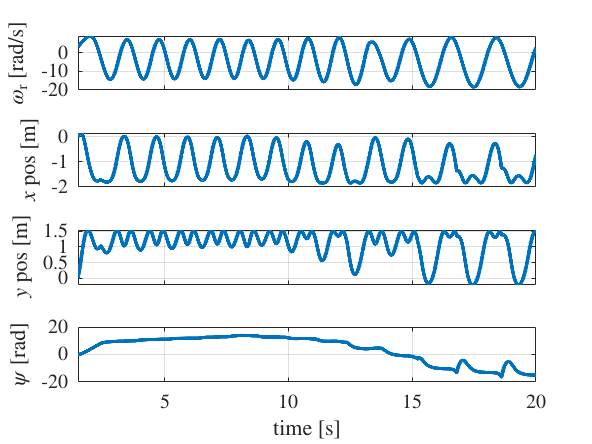


figure
subplot(4,1,1)
plot(time, wrode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$\omega_{\rm r}$ [rad/s]', 'Interpreter','latex')
subplot(4,1,2)
plot(time, xode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$x$ pos [m]', 'Interpreter','latex')
subplot(4,1,3)
plot(time, yode, 'linewidth', 2)
xlim([1.5,20])
grid on
ylabel('$y$ pos [m]', 'Interpreter','latex')
set(gca,'xticklabel',[])
subplot(4,1,4)
plot(time, psiode, 'linewidth', 2)
xlim([1.5,20])
grid on
ylabel('$\psi$ [rad]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')


% x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
% u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
% car = vehicle parameters see initCar.m for a description

% Definition of functions must be at the end of the script

function [dv, dbeta, dr] = rigid_body_dynamics(Fx, Fy, Mz, x, car)
    % inputs: Fx - longitudinal force at CG
    %         Fy - lateral force at CG
    %         Mz - rotation torque around CG
    %         x - vehicle states
    %         car - car parameters
    % Air drag parameters 
    Ca = 0.3;
    rho = 1.2;
    A = 2;
    beta = x(2);
    r = x(3);
    m = car.m;
    Iz = car.Iz;
    if x(1)~=0
        MassMatrix = [(1/(m*x(1))) 0 0;0 1/m 0;0 0 1/car.Iz];
        RotationMatrix = [-sin(beta) cos(beta) 0;cos(beta) sin(beta) 0;0 0 1];
        Load = [Fx; Fy; Mz];
        Load2 = [r;0;0];
       
        F_air_x = 0.5*Ca*rho*A*(x(1)*cos(x(2)))^2;
        F_air_y = 0.5*Ca*rho*A*(x(1)*sin(x(2)))^2;
        AirDrag = [F_air_x; F_air_y; 0];
        result = MassMatrix*RotationMatrix*(Load-AirDrag) - Load2;
        dbeta = result(1);
        dv    = result(2);
        dr    = result(3);
    else
        dv = 0;
        dr = 0;
        dbeta = 0;
    end
    
end

function [Fx, Fy, Mz] = steering_angle_projection(Fxf, Fyf, Fxr, Fyr, u, car)
    % inputs: Fxf - longitudinal force at the front axle
    %         Fyf - lateral force at the front axle
    %         Fxr - longitudinal force at the rear axle
    %         Fyr - lateral force at the rear axle
    %         Fy - lateral force at CG
    %         x - model states
    %         u - model inputs
    %         car - car parameters
    
    df = u(1);
    dr = u(2);
    lf = car.lf;
    lr = car.lr;
    ProjMat = [cos(df) -sin(df) cos(dr) -sin(dr);sin(df) cos(df) sin(dr) cos(dr);lf*sin(df) lf*cos(df) -lr*sin(dr) -lr*cos(dr)];
    ForceVector = [Fxf;Fyf;Fxr;Fyr];
    Result = ProjMat*ForceVector;
    Fx = Result(1);
    Fy = Result(2);
    Mz = Result(3);
end

function [Fxf, Fyf, Fxr, Fyr] = tire_models(af, ar, lambdaF, lambdaR, car)
    % inputs: af - sideslip angle of the front wheel
    %         ar - sideslip angle of the rear wheel
    %         lambdaF - slip ratio of the front wheel
    %         lambdaR - slip ration of the rear wheel
    %         car - car parameters
    
    Fzf = 9.81*car.m*car.lr/(car.lf+car.lr);
    Fzr = 9.81*car.m*car.lf/(car.lf+car.lr);

    % Tire parameters
    c_Dy = 1;
    c_By = 6.9;
    c_Cy = 1.8;
    c_Ey = 0.1;

    c_Dx = 1;
    c_Bx = 15;
    c_Cx = 1.7;
    c_Ex = -0.5;

    Fxf_raw = c_Dx*Fzf*sin(c_Cx*atan2(c_Bx*lambdaF-c_Ex*(c_Bx*lambdaF-atan2(c_Bx*lambdaF,1)),1));
    Fxr_raw = c_Dx*Fzr*sin(c_Cx*atan2(c_Bx*lambdaR-c_Ex*(c_Bx*lambdaR-atan2(c_Bx*lambdaR,1)),1));
    Fyf_raw = c_Dy*Fzf*sin(c_Cy*atan2(c_By*af-c_Ey*(c_By*af-atan2(c_By*af,1)),1));
    Fyr_raw = c_Dy*Fzr*sin(c_Cy*atan2(c_By*ar-c_Ey*(c_By*ar-atan2(c_By*ar,1)),1));

    beta_star_f = acos(abs(lambdaF)/sqrt(lambdaF^2+sin(af)^2));
    beta_star_r = acos(abs(lambdaR)/sqrt(lambdaR^2+sin(ar)^2));

    mu_xf_act = Fxf_raw/Fzf;
    mu_yf_act = Fyf_raw/Fzf;
    mu_xf_max = c_Dx;
    mu_yf_max = c_Dy;

    mu_xr_act = Fxr_raw/Fzr;
    mu_yr_act = Fyr_raw/Fzr;
    mu_xr_max = c_Dx;
    mu_yr_max = c_Dy;


    mu_xf = 1/sqrt((1/mu_xf_act)^2 + (tan(beta_star_f)/mu_yf_max)^2);
    mu_yf = tan(beta_star_f)/sqrt((1/mu_xf_max)^2 + (tan(beta_star_f)/mu_yf_act)^2);

    mu_xr = 1/sqrt((1/mu_xr_act)^2 + (tan(beta_star_r)/mu_yr_max)^2);
    mu_yr = tan(beta_star_r)/sqrt((1/mu_xr_max)^2 + (tan(beta_star_r)/mu_yr_act)^2);

    if (mu_xf_act~=0)
        Fxf = abs(mu_xf/mu_xf_act)*Fxf_raw;
    else
        Fxf = 0;
    end
    if (mu_yf_act~=0)
        Fyf = abs(mu_yf/mu_yf_act)*Fyf_raw;
    else 
        Fyf = 0;
    end
    if (mu_xr_act~=0)
        Fxr = abs(mu_xr/mu_xr_act)*Fxr_raw;
    else 
        Fxr = 0;
    end
    if (mu_yr_act~=0)
        Fyr = abs(mu_yr/mu_yr_act)*Fyr_raw;
    else
        Fyr = 0;
    end
end
function [af, ar, vxf, vxr] = wheel_kinematics(x, u, car)
    % inputs: x - model states
    %         u - model inputs
    %         car - car parameters    

    % TIP: to avoid numerical problems, use atan2
    % x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
    % u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
    % car = vehicle parameters see initCar.m for a description
    beta = x(2);
    df = u(1);
    dr = u(2);
    lf = car.lf;
    lr = car.lr;
    r  = x(3);
    v  = x(1);
    A_f = [cos(df) sin(df); -sin(df) cos(df)];
    B_f = [v*cos(beta);v*sin(beta)+lf*r];

    A_r = [cos(dr) sin(dr); -sin(dr) cos(dr)];
    B_r = [v*cos(beta);v*sin(beta)+lr*r];

    v_f = A_f*B_f;
    v_r = A_r*B_r;

    vxf = v_f(1);
    vyf = v_f(2);
    vxr = v_r(1);
    vyr = v_r(2);
    af = -atan2(vyf,abs(vxf));
    ar = -atan2(vyr,abs(vxr));
end

function [dwf, dwr] = wheel_dynamics(x, u, Fxf, Fxr, car)
    % inputs: x - model states
    %         u - model inputs
    %         car - car parameters    
    k = 0.01;
    Iw = 1;
    % x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
    % u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
    wf = x(4);
    wr = x(5);
    Tdf = u(3);
    Tbf = u(4);
    Tdr = u(5);
    Tbr = u(6);
    p  = car.rad;

    Fzf = 9.81*car.m*car.lr/(car.lf+car.lr);
    Fzr = 9.81*car.m*car.lf/(car.lf+car.lr);

    dwf = (1/Iw)*(Tdf-p*Fxf-sign(wf)*Tbf)-k*Fzf;
    dwr = (1/Iw)*(Tdr-p*Fxr-sign(wr)*Tbr)-k*Fzr;
end

function [lambdaF, lambdaR] = slip_ratios(vxf, vxr, x, car)
    % inputs: vxf - longitudinal travel velocity of the front axle
    %         vxr - longitudinal travel velocity of the rear axle
    %         x - model states
    %         u - model inputs
    %         car - car parameters    
    % x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
    % u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
    % car = vehicle parameters see initCar.m for a description
    wf = x(4);
    wr = x(5);
    p  = car.rad;
    lambdaF = (wf*p-vxf)/max(abs(wf*p),abs(vxf));
    if lambdaF<-1
        lambdaF=-1;
    end
    if lambdaF>1
        lambdaF=1;
    end
    lambdaR = (wr*p-vxr)/max(abs(wr*p),abs(vxr));
    if lambdaR<-1
        lambdaR=-1;
    end
    if lambdaR>1
        lambdaR=1;
    end
end

function xdot = single_track(time, x, u, car)  
    % x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
    % u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
    % car = vehicle parameters
    
    [af, ar, vxf, vxr] = wheel_kinematics(x, u, car);
    [lambdaF, lambdaR] = slip_ratios(vxf, vxr, x, car);
    [Fxf, Fyf, Fxr, Fyr] = tire_models(af, ar, lambdaF, lambdaR, car);
    [Fx, Fy, Mz] = steering_angle_projection(Fxf, Fyf, Fxr, Fyr, u, car);
    [dv,dbeta,dr] = rigid_body_dynamics(Fx, Fy, Mz, x, car);
    [dwf, dwr] = wheel_dynamics(x, u, Fxf, Fxr, car);
     dv = dv;
     dbeta =dbeta;
     dr = dr;
     dwf = dwf;
     dwr = dwr;

     beta = x(1);
     dx = dv*cos(beta);
     dy = dv*sin(beta);
     dpsi = dr*time;
    
    xdot = [dv, dbeta, dr, dwf, dwr, dx, dy, dpsi]';
end

### References

[1] V. Cibulka, Twin-track model implementation. Available online at *https://github.com/SDS-RC-FEE-CTU-in-Prague/TwinTrack*.

[2] D. Schramm, M. Hiller, and R. Bardini, *Vehicle dynamics, Modeling and Simulation*. Springer, 2014.

Equations are there: Full-model -> PDF

[3] D. Efremov, Single-track model implementation. Available online at *https://github.com/SDS-RC-FEE-CTU-in-Prague/SingleTrack*.